## **setup /scan data**

clear;
filename = "focus_scan_zigzag.csv"'

filename = "focus_scan_zigzag.csv"

scans_data = readtable(filename)

scans_data = 196×92 table
     Var1       Var2       Var3       Var4      Var5       Var6       Var7       Var8       Var9      Var10      Var11      Var12      Var13      Var14      Var15      Var16      Var17      Var18      Var19      Var20      Var21      Var22     Var23      Var24      Var25      Var26      Var27      Var28      Var29      Var30      Var31      Var32      Var33      Var34      Var35


angles = scans_data{1, :}

angles =   -18.9844  -18.6328  -18.2812  -17.9297  -17.5781  -17.2266  -16.8750  -16.5234  -16.1719  -15.8203  -15.4687  -15.1172  -14.7656  -14.4141  -14.0625  -13.7109  -13.3594  -13.0078  -12.6562  -12.3047  -11.9531  -11.6016  -11.2500  -10.8984  -10.5469  -10.1953   -9.8437   -9.4922   -9.1406   -8.7891   -8.4375   -8.0859   -7.7344   -7.3828   -7.0312   -6.6797   -6.3281   -5.9766   -5.6250   -5.2734   -4.9219   -4.5703   -4.2187   -3.8672   -3.5156   -3.1641   -2.8125   -2.4609   -2.1094   -1.7578


total_frame = size(scans_data,1)

total_frame = 196

data_point = size(angles,2)

data_point = 92


% Plotting Colors
ax = gca;

function savgol_filter = SalGov(data_file,frame,poly,win)
    scans_data = readtable(data_file);
    scan = scans_data{frame, :};
    savgol_filter = sgolayfilt(scan, poly, win);
end

disp("Setup Complete.")

Setup Complete.


## **Fine-tuning Savitzky–Golay Params**

scan_index = 105;
scan = scans_data{scan_index, :}

scan =     0.1150    0.1150    0.1150    0.1150    0.1140    0.1140    0.1140    0.1120    0.1120    0.1110    0.1110    0.1110    0.1100    0.1100    0.1120    0.1120    0.1120    0.1120    0.1120    0.1120    0.1120    0.1120    0.1090    0.1090    0.1090    0.1100    0.1100    0.1100    0.1110    0.1110    0.1100    0.1100    0.1080    0.1080    0.1080    0.1080    0.1100    0.1100    0.1100    0.1100    0.1100    0.1120    0.1120    0.1080    0.1080    0.1130    0.1130    0.1130    0.1130    0.1130


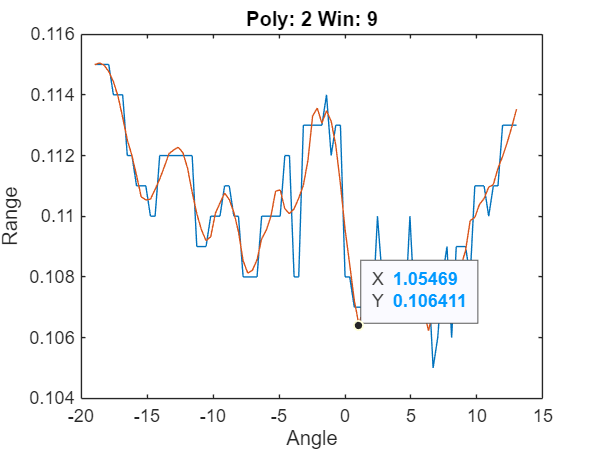

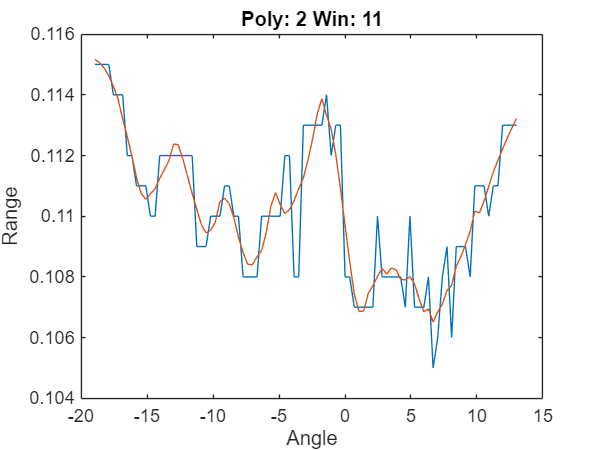

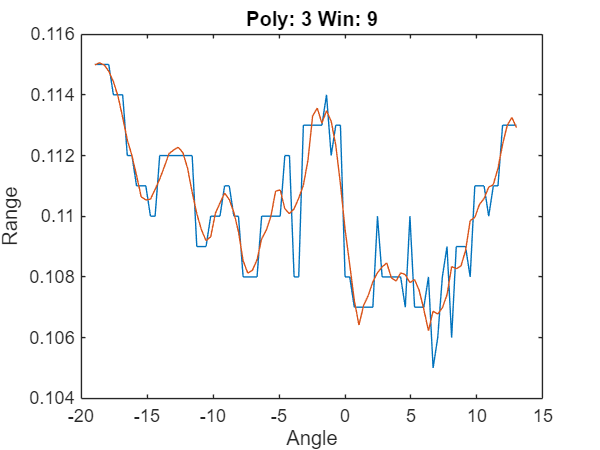

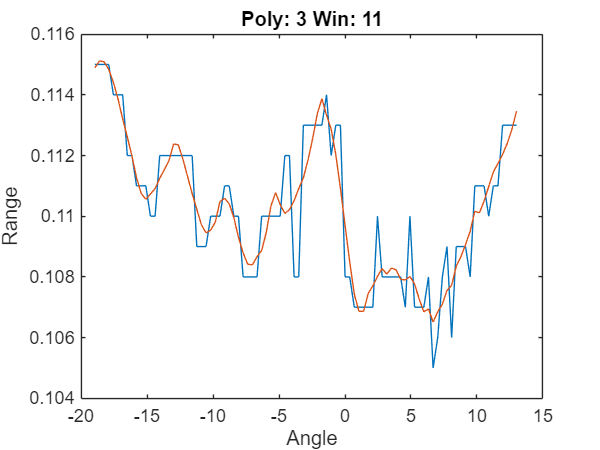

for poly = 2:3
    for win = 9:2:11
        figure()
        plot(angles, scan)
        xlabel('Angle'); ylabel('Range'); 
        hold on
        savgol = sgolayfilt(scan, poly, win);
        plot(angles, savgol)
        title("Poly: " + poly + " Win: " + win);
        hold off
    end
end

### Test with random sample

scan_index = 160

scan =     0.1690    0.1690    0.1690    0.1690    0.1650    0.1630    0.1620    0.1620    0.1620    0.1620    0.1670    0.1680    0.1680    0.1680    0.1640    0.1600    0.1600    0.1590    0.1600    0.1670    0.1680    0.1680    0.1680    0.1680    0.1640    0.1630    0.1620    0.1560    0.1560    0.1560    0.1560    0.1570    0.1570    0.1560    0.1550    0.1550    0.1550    0.1550    0.1550    0.1570    0.1640    0.1640    0.1640    0.1650    0.1640    0.1550    0.1550    0.1550    0.1540    0.1550


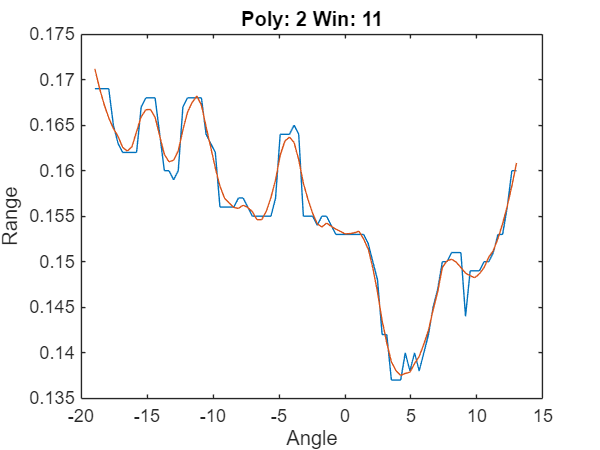

scan_index = 178

scan =     0.1300    0.1310    0.1310    0.1350    0.1350    0.1360    0.1360    0.1350    0.1350    0.1330    0.1330    0.1280    0.1270    0.1270    0.1290    0.1270    0.1270    0.1270    0.1260    0.1230    0.1230    0.1230    0.1230    0.1250    0.1250    0.1250    0.1250    0.1220    0.1220    0.1220    0.1210    0.1220    0.1210    0.1210    0.1210    0.1200    0.1200    0.1200    0.1220    0.1210    0.1220    0.1210    0.1210    0.1170    0.1170    0.1170    0.1160    0.1160    0.1160    0.1140


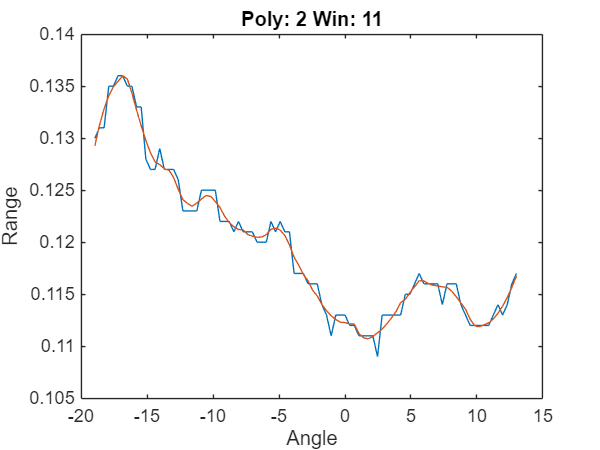

scan_index = 25

scan =     0.1820    0.1820    0.1820    0.1800    0.1780    0.1750    0.1720    0.1720    0.1710    0.1710    0.1720    0.1720    0.1710    0.1720    0.1730    0.1720    0.1710    0.1660    0.1660    0.1660    0.1690    0.1690    0.1710    0.1710    0.1710    0.1710    0.1730    0.1730    0.1730    0.1710    0.1730    0.1730    0.1730    0.1650    0.1730    0.1680    0.1670    0.1670    0.1680    0.1680    0.1670    0.1620    0.1620    0.1590    0.1590    0.1590    0.1590    0.1580    0.1580    0.1580


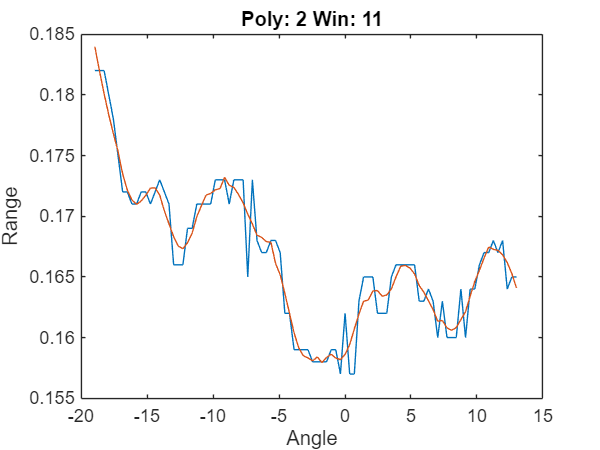

scan_index = 180

scan =     0.1440    0.1440    0.1460    0.1460    0.1440    0.1440    0.1440    0.1400    0.1400    0.1410    0.1390    0.1410    0.1410    0.1420    0.1410    0.1420    0.1420    0.1420    0.1420    0.1420    0.1350    0.1350    0.1340    0.1350    0.1350    0.1350    0.1350    0.1370    0.1370    0.1370    0.1380    0.1380    0.1310    0.1310    0.1350    0.1340    0.1340    0.1350    0.1350    0.1360    0.1360    0.1360    0.1340    0.1330    0.1250    0.1250    0.1290    0.1270    0.1290    0.1290


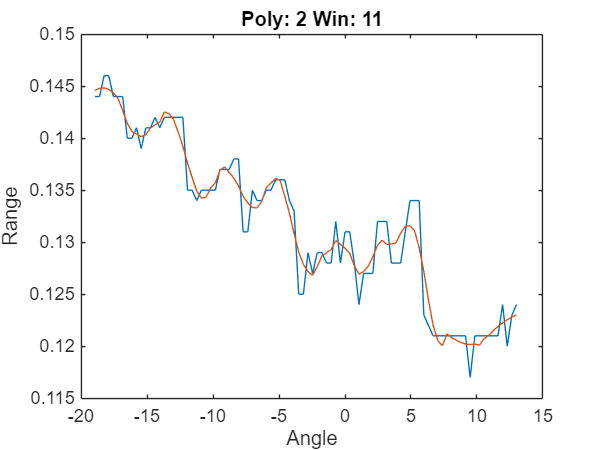

scan_index = 124

scan =     0.1110    0.1110    0.1100    0.1090    0.1090    0.1080    0.1060    0.1080    0.1060    0.1050    0.1030    0.1030    0.1010    0.1030    0.1010    0.1010    0.1010    0.1030    0.1030    0.1090    0.1080    0.1080    0.1080    0.1080    0.1050    0.1020    0.1050    0.1050    0.1030    0.0960    0.0980    0.0970    0.0970    0.0980    0.0990    0.1000    0.1010    0.1030    0.1030    0.1030    0.1030    0.1010    0.1010    0.1010    0.1010    0.0980    0.0980    0.0980    0.0980    0.0980


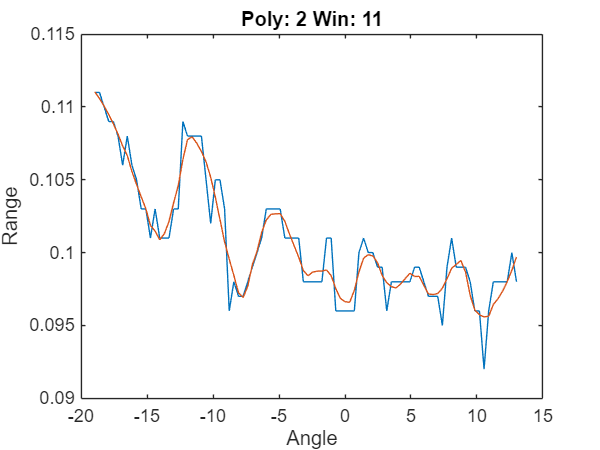

poly = 2; win = 11;
for i = 1:5
    scan_index = randi([1,total_frame])
    scan = scans_data{scan_index, :}
    figure()
    plot(angles, scan)
    xlabel('Angle'); ylabel('Range'); 
    hold on
    savgol = sgolayfilt(scan, poly, win);
    plot(angles, savgol)
    title("Poly: " + poly + " Win: " + win);
    hold off
end

### Video From Sample

xlimVals = [min(angles) max(angles)];
ylimVals = [0.1 0.3];
v = VideoWriter('scan_video2.mp4','MPEG-4');
v.FrameRate = 10;
open(v);

figure('Color','w');
for scan_index = 1:total_frame
    disp('frame: ' + scan_index)
    scan = scans_data{scan_index, :};
    clf
    plot(angles, scan);
    filter_data = SalGov(filename,scan_index,2,11);
    hold on;
    plot(angles,filter_data);
    xlim(xlimVals); ylim(ylimVals);
    xlabel('Angle'); ylabel('Range');
    drawnow
    writeVideo(v, getframe(gcf));
    hold off
end
close(v);

disp('Saved scan_video.mp4');

## Find Peaks

figure()
hold on

for test_frame = 51
scan = scans_data{test_frame, :}


%plot(angles, scan);

filter_data = SalGov(filename, test_frame, 2, 11);

% Find single best valley (peak of -filter_data) in x-units
[pksN, locs] = findpeaks(-filter_data, angles, ...
    'MinPeakProminence', 0.001, 'SortStr','descend', 'NPeaks', 5);

% Plot filtered signal (optional)
plot(angles, filter_data,'DisplayName',string(test_frame));

% Vertical line at best valley
if isempty(locs) == false
    xline(locs);
end

% Cosmetics
if exist('xlimVals','var'), xlim(xlimVals); end
if exist('ylimVals','var'), ylim(ylimVals); end
xlabel('Angle'); ylabel('Range'); 


end

scan =     0.1090    0.1080    0.1080    0.1080    0.1080    0.1080    0.1060    0.1060    0.1080    0.1060    0.1070    0.1070    0.1070    0.1070    0.1070    0.1070    0.1070    0.1040    0.1040    0.1040    0.1030    0.1030    0.1030    0.1030    0.1030    0.1060    0.1060    0.1060    0.1060    0.1060    0.1050    0.1060    0.1050    0.1030    0.1030    0.1040    0.1030    0.1040    0.1040    0.1050    0.1050    0.1050    0.1040    0.1030    0.1030    0.1040    0.1040    0.1040    0.1050    0.1050


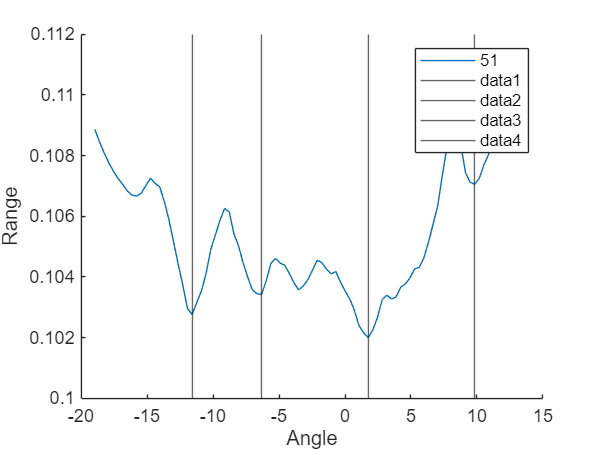

legend('Location','Northeast')
hold off

#### Plot best_angle vs time

best_angle_SalGov = zeros(1,total_frame);
best_angle_Min = zeros(1,total_frame);

for frame = 1:total_frame
    scan = scans_data{frame, :};
    filter_data = SalGov(filename, frame, 2, 11);
    [pksN, locs] = findpeaks(-filter_data, angles,'MinPeakProminence', 0.008, 'SortStr','descend', 'NPeaks', 5);
    if isempty(locs) 
        best_angle_SalGov(1,frame) = NaN;
    else
        best_angle_SalGov(1,frame) = locs;
    end

    [min_ranges, min_idx] = min(scan);
    best_angle_Min(frame) = angles(1,min_idx);
end

time = 0:20/(total_frame-1):20

time =          0    0.1026    0.2051    0.3077    0.4103    0.5128    0.6154    0.7179    0.8205    0.9231    1.0256    1.1282    1.2308    1.3333    1.4359    1.5385    1.6410    1.7436    1.8462    1.9487    2.0513    2.1538    2.2564    2.3590    2.4615    2.5641    2.6667    2.7692    2.8718    2.9744    3.0769    3.1795    3.2821    3.3846    3.4872    3.5897    3.6923    3.7949    3.8974    4.0000    4.1026    4.2051    4.3077    4.4103    4.5128    4.6154    4.7179    4.8205    4.9231    5.0256


frames = 1:total_frame

frames =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


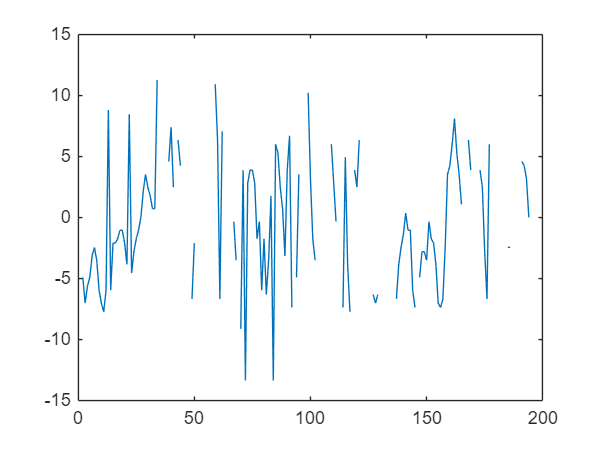


% SalGov
figure()
plot(frames,best_angle_SalGov,'Color', ax.ColorOrder(1,:),'DisplayName','SalGov + findPeaks')

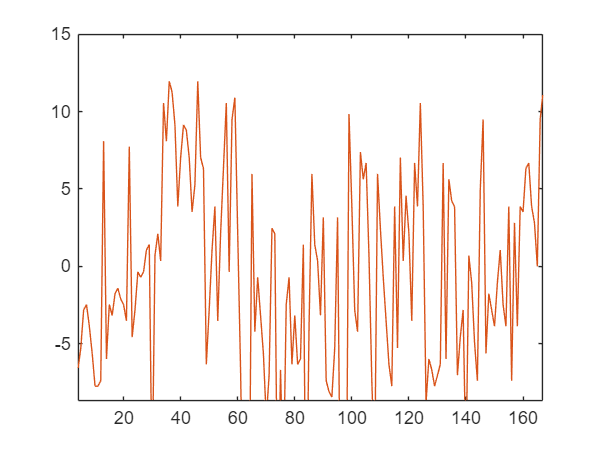


% Minimum
figure()
plot(frames, best_angle_Min,'Color', ax.ColorOrder(2,:), 'DisplayName','Minimum Values')

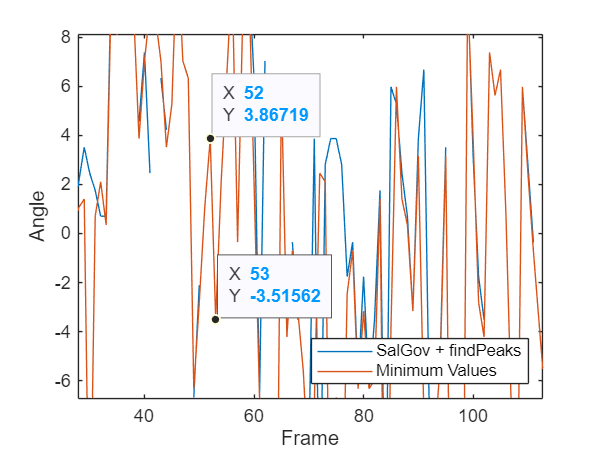


% Combined Plot
figure()
plot(frames,best_angle_SalGov,'DisplayName','SalGov + findPeaks')
hold on
plot(frames, best_angle_Min, 'DisplayName','Minimum Values')
xlabel('Frame'); ylabel('Angle');
legend('Location','Southeast');
% xlabel('time'); ylabel('Angle'); 
hold off

#### Testing Video for Peak Finding

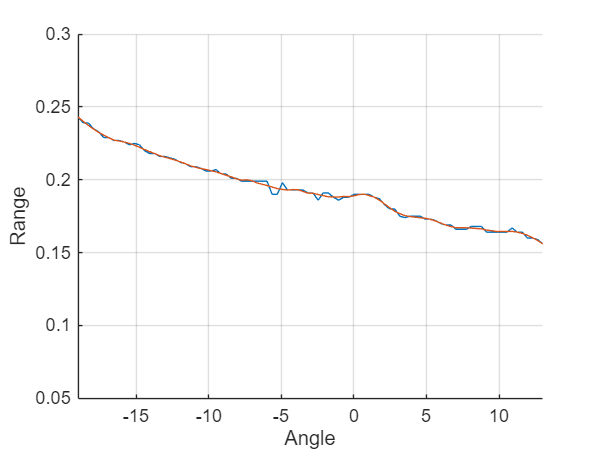

xlimVals = [min(angles) max(angles)];
ylimVals = [0.05 0.3];

videoname = 'scan_video_peak3.mp4'
v = VideoWriter(videoname,'MPEG-4');
v.FrameRate = 8; 
open(v);

fig = figure('Color','w');
ax  = axes('Parent',fig, 'NextPlot','add');  % keep plots; like hold on

% Precreate plot objects
hScan = plot(ax, angles, nan(size(angles)), 'DisplayName','Scan');
hFilt = plot(ax, angles, nan(size(angles)), 'DisplayName','Filtered');

% Precreate a vertical line using LINE (not xline)
hV = line(ax, [NaN NaN], ylimVals, 'Color','r', 'LineStyle','-','DisplayName','Best valley');   % starts hidden (NaN XData)

xlim(ax, xlimVals); ylim(ax, ylimVals);
xlabel(ax,'Angle'); ylabel(ax,'Range'); grid(ax,'on');

for scan_index = 1:total_frame
    scan        = scans_data{scan_index, :};
    filter_data = SalGov(filename, scan_index, 2, 11);

    % Update traces
    set(hScan, 'YData', scan);
    set(hFilt, 'YData', filter_data);

    % Best valley
    [pksN, locs] = findpeaks(-filter_data, angles, ...
        'MinPeakProminence', 0.007,'MinPeakDistance',0.01, 'SortStr','descend', 'NPeaks', 1);

    if isempty(locs)
        % hide line by NaN-ing XData
        set(hV, 'XData', [NaN NaN], 'Color','r', 'Visible','on');   % color forced red
    else
        % ensure limits first (so YData spans correctly), then move the line
        ylim(ax, ylimVals);
        set(hV, 'XData', [locs locs], 'YData', ylim(ax), 'Color','r', 'Visible','on');
    end

    drawnow
    writeVideo(v, getframe(fig));
end


close(v);
disp('Saved scan_video_peak3.mp4');

Saved scan_video_peak3.mp4


## Unofficial Sandbox Zone

### Karlman + SalGov + find_peaks

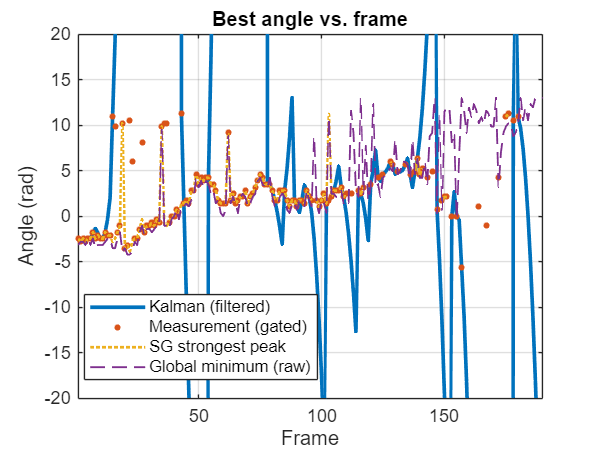

%% ================================================================
%  Weld-bead angle tracker: Median + SG (SalGov) + top-3 peaks + KF(CA)
%  - Warm-start (collect first N_INIT good measurements)
%  - Soft-start (R ramp-down)
%  - Mahalanobis-gated update
%  - Plots best_angle vs frame
%  ---------------------------------------------------------------
%  Author: you + Chat :)
%  Date  : 2025-11-01
%% ================================================================

clc; clear; close all;

%% ---------- 0) Load data ----------
filename = "focus_scan_straight.csv";
scans_data = readtable(filename);

angles = scans_data{1, :};         % row 1 = angle grid
data_rows = 2:height(scans_data);  % rows with scans
total_frame = numel(data_rows);

% Display units toggle (true = show plot in degrees; internals can stay radians)
use_degrees = false;

%% ---------- 1) Outputs ----------
best_angle_SalGov = nan(1, total_frame);  % strongest peak (SG-only, ref)
best_angle_Min    = nan(1, total_frame);  % global min on raw (ref)
best_angle_meas   = nan(1, total_frame);  % chosen/gated measurement
best_angle_KF     = nan(1, total_frame);  % KF filtered angle

%% ---------- 2) Peak-detection knobs ----------
% We detect minima by running findpeaks on -SG_output.
PROM_FRAC     = 0.20;    % 20% of IQR as adaptive prominence
PROM_ABS_MIN  = 0.05;    % floor for tiny signals (same units as range)
MIN_DIST      = 5;       % min distance between peaks (samples)
WIDTH_LIM     = [1 40];  % allowable peak width (samples)
TOP_K         = 3;       % keep top-K per frame

% If you pass X to findpeaks, widths are in angle units. Otherwise, samples.
USE_X_IN_FINDPEAKS = true;
W_NOM = 8;               % nominal width (same units as 'widths' from findpeaks)

% Optional candidate ranking weights
W_PROM = 1.0;  % prominence weight
W_PKHT = 0.5;  % (neg)peak height on -y
W_WPEN = 0.3;  % |width - W_NOM| penalty weight

%% ---------- 3) Kalman Filter (Constant-Acceleration model) ----------
% State x = [theta; theta_dot; theta_ddot]
dt = 1;  % set to real frame interval if not 1

F = [1  dt  0.5*dt^2;
     0   1          dt;
     0   0           1];
H = [1 0 0];

% Process noise (white jerk): q ↑ → follows bends more
q = 0.08;
Q = q * [dt^5/20, dt^4/8,  dt^3/6;
         dt^4/8,  dt^3/3,  dt^2/2;
         dt^3/6,  dt^2/2,  dt];

% Measurement noise variance (angle^2) — tune to your units
R_nom = 5e-4;       % if angles are radians; if degrees, consider ~0.02 (deg^2)
R     = 5*R_nom;    % start softer (trust measurements less), ramp to R_nom
R_decay_frames = 10;

x = [0;0;0];
P = eye(3)*1e2;

gate_k2 = 12.0;     % Mahalanobis gate (~3.46σ^2). Loosen to 16 if needed.

% Warm-start buffer
N_INIT = 5;
init_buf = nan(1, N_INIT);
have_init = false;
frames_since_init = 0;

%% ---------- 4) Main loop ----------
for f = 1:total_frame
    row = data_rows(f);
    raw = scans_data{row, :};

    % -- Preprocess raw --
    raw = fillmissing(raw, 'linear');
    raw = movmedian(raw, 5);         % de-spike

    % -- Savitzky–Golay (your helper) --
    y = SalGov(filename, row, 2, 11);  % keep your tuned (poly=2, win=11)

    % -- Baseline refs (optional) --
    [~, min_idx] = min(raw);
    best_angle_Min(f) = angles(min_idx);

    baseScale = iqr(y);
    prom_th = 0.007;

    % Strongest single minimum (SG-only)
    if USE_X_IN_FINDPEAKS
        [pks1, locs1] = findpeaks(-y, angles, ...
            'MinPeakProminence', prom_th, ...
            'SortStr','descend', 'NPeaks', 1);
    else
        [pks1, loc_inds1] = findpeaks(-y, ...
            'MinPeakProminence', prom_th, ...
            'SortStr','descend', 'NPeaks', 1);
        if ~isempty(loc_inds1)
            locs1 = angles(loc_inds1);
        else
            locs1 = [];
        end
    end
    if isempty(locs1)
        best_angle_SalGov(f) = NaN;
    else
        best_angle_SalGov(f) = locs1(1);
    end

    % -- Top-K candidates (minima on -y) --
    if USE_X_IN_FINDPEAKS
        [pks, locs, widths, proms] = findpeaks(-y, angles, ...
            'MinPeakProminence', prom_th, ...
            'SortStr','descend', 'NPeaks', TOP_K);
    else
        [pks, loc_inds, widths, proms] = findpeaks(-y, ...
            'MinPeakProminence', prom_th, ...
            'SortStr','descend', 'NPeaks', TOP_K);
        if ~isempty(loc_inds)
            locs = angles(loc_inds);
        else
            locs = [];
        end
    end

    % Optional: re-rank by score (prominence/height − width penalty)
    if ~isempty(locs)
        width_pen = abs(widths - W_NOM);
        score = W_PROM*proms + W_PKHT*pks - W_WPEN*width_pen;
        [~, ord] = sort(score, 'descend');
        locs = locs(ord);
    end

    % -- KF predict (CA model) --
    x_pred = F*x;
    P_pred = F*P*F' + Q;

    % -- Choose candidate by Mahalanobis gating vs prediction --
    z_star = NaN; d2_star = inf;
    if ~isempty(locs)
        S = H*P_pred*H' + R;      % scalar
        for i = 1:numel(locs)
            z = locs(i);
            ytil = z - H*x_pred;  % innovation
            d2 = (ytil / S) * ytil;
            if d2 < d2_star
                d2_star = d2; z_star = z;
            end
        end
    end

    % -- Warm-start collection (no p0 reference before it exists) --
    if ~have_init
        best_angle_meas(f) = z_star;   % log whatever we saw (may be NaN)

        if ~isnan(z_star)
            init_buf = [init_buf(2:end), z_star];
        end

        if all(~isnan(init_buf))
            % Init state from median & slope of first N_INIT good frames
            p0 = median(init_buf);
            t0 = (0:N_INIT-1) * dt;
            coeff = polyfit(t0, init_buf, 1);   % slope = velocity
            v0 = coeff(1);

            x = [p0; v0; 0];
            P = diag([1e-3, 1e-2, 1e-1]);
            have_init = true;
            frames_since_init = 0;

            best_angle_KF(f) = x(1);   % filtered output at init
        else
            best_angle_KF(f) = NaN;    % not initialized yet
        end

        continue  % stay in warm-start until have_init is true
    end

    % -- After init: innovation + gating (start-up protections) --
    if ~isnan(z_star)
        ytil = z_star - H*x_pred;
        S    = H*P_pred*H' + R;
        d2   = (ytil / S) * ytil;

        % Clip innovation early to avoid big first jumps
        if frames_since_init < 5
            max_jump = 3 * sqrt(S);
            ytil = max(min(ytil, max_jump), -max_jump);
            d2   = (ytil / S) * ytil; % recompute
        end

        if d2 <= gate_k2
            K = (P_pred * H') / S;    % 3x1
            x = x_pred + K * ytil;
            P = (eye(3) - K*H) * P_pred;
        else
            x = x_pred; P = P_pred;   % reject outlier
        end
    else
        x = x_pred; P = P_pred;       % no measurement
    end

    % -- Soft-start: ramp R toward nominal over R_decay_frames --
    frames_since_init = frames_since_init + 1;
    if frames_since_init < R_decay_frames
        alpha = frames_since_init / R_decay_frames; % 0→1
        R = (1-alpha) * (5*R_nom) + alpha * R_nom;
    else
        R = R_nom;
    end

    % -- Save outputs --
    best_angle_meas(f) = z_star;
    best_angle_KF(f)   = x(1);
end

%% ---------- 5) Plot: best angle vs frame ----------
frames = 1:total_frame;

ang_KF   = best_angle_KF;
ang_meas = best_angle_meas;
ang_SG   = best_angle_SalGov;
ang_min  = best_angle_Min;

if use_degrees
    ang_KF   = rad2deg(ang_KF);
    ang_meas = rad2deg(ang_meas);
    ang_SG   = rad2deg(ang_SG);
    ang_min  = rad2deg(ang_min);
    ylab = 'Angle (deg)';
else
    ylab = 'Angle (rad)';
end

figure; hold on
plot(frames, ang_KF,   'LineWidth', 2,  'DisplayName','Kalman (filtered)');
plot(frames, ang_meas, '.',         'MarkerSize', 10, 'DisplayName','Measurement (gated)');
plot(frames, ang_SG,   ':',         'LineWidth', 1.5,'DisplayName','SG strongest peak');
plot(frames, ang_min,  '--',        'LineWidth', 1,  'DisplayName','Global minimum (raw)');
xlabel('Frame'); ylabel(ylab);
title('Best angle vs. frame'); legend('Location','best');
grid on; box on; xlim([1 total_frame]);ylim([-20 20])

- SalGov → **Smooth Data **→ *Params: poly, win*

- findPeaks → **Find candidates of Best Weld Angle** → *Parms: Prominence, width, height*

- Best Weld Angle → Angle vs Frame

- **Algorithm to choose the most reasonable weld angle based on past angles data**